%Read .dat files into a table for cleaning and processing

ramp_desc_lg_trial_01 = readtable("ramp_desc_lg_trial_01.dat");

%cleaning columns for removing junk data: Annotations, Shank_L 1&2

rampdesc_lg_01_clean = removevars(ramp_desc_lg_trial_01,{'Annotation','Annotation_1','Shank_L_1','Shank_L_2'});

%cleaning NaN values (removing rows?) using rmmissing
%% sittostand_jun_01_clean = rmmissing(sittostand_jun_trial_02);

%no NaN values in this set of data. Hence not implementing the rmmissing code
%figure1 = plot(sittostand_jun_02_clean,"Thigh_R","Thigh_R_1")

rampdesc_lg_01_clean_1 = renamevars(rampdesc_lg_01_clean,["Thigh_R","Shank_R","Foot_R","Thigh_L","Shank_L","Foot_L","Pelvis"],["Thigh_R_Time","Shank_R_Time","Foot_R_Time","Thigh_L_Time","Shank_L_Time","Foot_L_Time","Pelvis_Time"]);
rampdesc_lg_01_clean_1 = renamevars(rampdesc_lg_01_clean_1,["Shank_L_3","Shank_L_4","Shank_L_5","Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9","Shank_L_10","Shank_L_11"],["Shank_L_1","Shank_L_2","Shank_L_3","Shank_L_4","Shank_L_5","Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9"]);

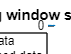

% Filtering for Thigh_R
% Smooth input data
[rampdesc_lg_01_filtered_thigh_r,winSize] = smoothdata(rampdesc_lg_01_clean_1, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Thigh_R_1","Thigh_R_2","Thigh_R_3","Thigh_R_4","Thigh_R_5", ...
    "Thigh_R_6","Thigh_R_7","Thigh_R_8","Thigh_R_9"], ...
    "SamplePoints",rampdesc_lg_01_clean_1.Thigh_R_Time);

% Display results
figure
plot(rampdesc_lg_01_clean_1.Thigh_R_Time,rampdesc_lg_01_clean_1.Thigh_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampdesc_lg_01_clean_1.Thigh_R_Time,rampdesc_lg_01_filtered_thigh_r.Thigh_R_1,"SeriesIndex",1, ...
    "LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize));
legend
ylabel("Thigh_R_1","Interpreter","none")
xlabel("Thigh_R_Time","Interpreter","none")

clear winSize

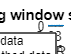

% Filtering for Shank_R
% Smooth input data
[rampdesc_lg_01_filtered_shank_r,winSize2] = smoothdata(rampdesc_lg_01_filtered_thigh_r, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Shank_R_1","Shank_R_2","Shank_R_3","Shank_R_4","Shank_R_5", ...
    "Shank_R_6","Shank_R_7","Shank_R_8","Shank_R_9"], ...
    "SamplePoints",rampdesc_lg_01_filtered_thigh_r.Shank_R_Time);

% Display results
figure
plot(rampdesc_lg_01_filtered_thigh_r.Shank_R_Time,rampdesc_lg_01_filtered_thigh_r.Shank_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampdesc_lg_01_filtered_thigh_r.Shank_R_Time,rampdesc_lg_01_filtered_shank_r.Shank_R_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize2));
legend
ylabel("Shank_R_1","Interpreter","none")
xlabel("Shank_R_Time","Interpreter","none")

clear winSize2

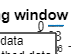

% Filtering for Foot_R
% Smooth input data
[rampdesc_lg_01_filtered_foot_r,winSize3] = smoothdata(rampdesc_lg_01_filtered_shank_r, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Foot_R_1","Foot_R_2","Foot_R_3","Foot_R_4","Foot_R_5", ...
    "Foot_R_6","Foot_R_7","Foot_R_8","Foot_R_9"], ...
    "SamplePoints",rampdesc_lg_01_filtered_shank_r.Foot_R_Time);

% Display results
figure
plot(rampdesc_lg_01_filtered_shank_r.Foot_R_Time,rampdesc_lg_01_filtered_shank_r.Foot_R_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampdesc_lg_01_filtered_shank_r.Foot_R_Time,rampdesc_lg_01_filtered_foot_r.Foot_R_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize3));
legend
ylabel("Foot_R_1","Interpreter","none")
xlabel("Foot_R_Time","Interpreter","none")

clear winSize3

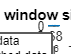

% Filtering for Thigh_L
% Smooth input data
[rampdesc_lg_01_filtered_thigh_l,winSize4] = smoothdata(rampdesc_lg_01_filtered_foot_r, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Thigh_L_1","Thigh_L_2","Thigh_L_3","Thigh_L_4","Thigh_L_5", ...
    "Thigh_L_6","Thigh_L_7","Thigh_L_8","Thigh_L_9"], ...
    "SamplePoints",rampdesc_lg_01_filtered_foot_r.Thigh_L_Time);

% Display results
figure
plot(rampdesc_lg_01_filtered_foot_r.Thigh_L_Time,rampdesc_lg_01_filtered_foot_r.Thigh_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampdesc_lg_01_filtered_foot_r.Thigh_L_Time,rampdesc_lg_01_filtered_thigh_l.Thigh_L_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize4));
legend
ylabel("Thigh_L_1","Interpreter","none")
xlabel("Thigh_L_Time","Interpreter","none")

clear winSize4

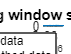

% Filtering for Shank_L
% Smooth input data
[rampdesc_lg_01_filtered_shank_l,winSize5] = smoothdata(rampdesc_lg_01_filtered_thigh_l, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Shank_L_1","Shank_L_2","Shank_L_3","Shank_L_4","Shank_L_5", ...
    "Shank_L_6","Shank_L_7","Shank_L_8","Shank_L_9"], ...
    "SamplePoints",rampdesc_lg_01_filtered_thigh_l.Shank_L_Time);

% Display results
figure
plot(rampdesc_lg_01_filtered_thigh_l.Shank_L_Time,rampdesc_lg_01_filtered_thigh_l.Shank_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampdesc_lg_01_filtered_thigh_l.Shank_L_Time,rampdesc_lg_01_filtered_shank_l.Shank_L_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize5));
legend
ylabel("Shank_L_1","Interpreter","none")
xlabel("Shank_L_Time","Interpreter","none")

clear winSize5

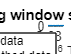

% Filtering for Foot_L
% Smooth input data
[rampdesc_lg_01_filtered_foot_l,winSize6] = smoothdata(rampdesc_lg_01_filtered_shank_l, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Foot_L_1","Foot_L_2","Foot_L_3","Foot_L_4","Foot_L_5", ...
    "Foot_L_6","Foot_L_7","Foot_L_8","Foot_L_9"], ...
    "SamplePoints",rampdesc_lg_01_filtered_shank_l.Foot_L_Time);

% Display results
figure
plot(rampdesc_lg_01_filtered_shank_l.Foot_L_Time,rampdesc_lg_01_filtered_shank_l.Foot_L_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampdesc_lg_01_filtered_shank_l.Foot_L_Time,rampdesc_lg_01_filtered_foot_l.Foot_L_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize6));
legend
ylabel("Foot_L_1","Interpreter","none")
xlabel("Foot_L_Time","Interpreter","none")

clear winSize6

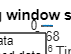

% Filtering for Pelvis - Final
% Smooth input data
[rampdesc_lg_01_filtered_final,winSize7] = smoothdata(rampdesc_lg_01_filtered_foot_l, ...
    "movmean","SmoothingFactor",0.25, ...
    "DataVariables",["Pelvis_1","Pelvis_2","Pelvis_3","Pelvis_4","Pelvis_5", ...
    "Pelvis_6","Pelvis_7","Pelvis_8","Pelvis_9"], ...
    "SamplePoints",rampdesc_lg_01_filtered_foot_l.Pelvis_Time);

% Display results
figure
plot(rampdesc_lg_01_filtered_foot_l.Pelvis_Time,rampdesc_lg_01_filtered_foot_l.Pelvis_1, ...
    "SeriesIndex",6,"DisplayName","Input data")
hold on
plot(rampdesc_lg_01_filtered_foot_l.Pelvis_Time,rampdesc_lg_01_filtered_final.Pelvis_1, ...
    "SeriesIndex",1,"LineWidth",1.5,"DisplayName","Smoothed data")
hold off
title("Moving window size: " + string(winSize7));
legend
ylabel("Pelvis_1","Interpreter","none")
xlabel("Pelvis_Time","Interpreter","none")

clear winSize7

% Process TR section
TR_tables = Sliding_Window(rampdesc_lg_01_filtered_final, 'Thigh_R');

% Process SR section
SR_tables = Sliding_Window(rampdesc_lg_01_filtered_final, 'Shank_R');

%Process FR section
FR_tables = Sliding_Window(rampdesc_lg_01_filtered_final, 'Foot_R');

%Process TL section
TL_tables = Sliding_Window(rampdesc_lg_01_filtered_final, 'Thigh_L');

%Process SL section
SL_tables = Sliding_Window(rampdesc_lg_01_filtered_final, 'Shank_L');

%Process FL section
FL_tables = Sliding_Window(rampdesc_lg_01_filtered_final, 'Foot_L');

%Process P section
P_tables = Sliding_Window(rampdesc_lg_01_filtered_final, 'Pelvis');

% Combine results
Var_Names = {'Max', 'Min', 'Mean', 'RMS', 'MaxGrad', 'STD', 'ZC'};
for v = 1:length(Var_Names)
    Combined_Table = [TR_tables.(Var_Names{v}), SR_tables.(Var_Names{v}), FR_tables.(Var_Names{v}), TL_tables.(Var_Names{v}), SL_tables.(Var_Names{v}), FL_tables.(Var_Names{v}), P_tables.(Var_Names{v})];
    assignin('base', ['Dsc_' Var_Names{v} '_L1'], Combined_Table);
end